clc
V1=[];
V2=[];
for F=40:0.1:60
    for P=10:1:70
        V1=[V1; Interpola(F,P,MatrizSimulador,3)];
        V2=[V2; full(f_Interpola_casadi_vazao_sym(F,P))];
    end
end
ErroMax=max(V1-V2)

ErroMax = 77.1850

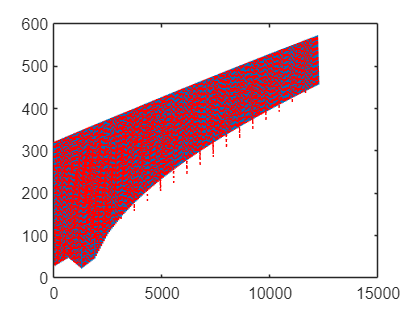

close all
plot(V1)
hold on
plot(V2,'r:')